# **META 2**

10. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    amplitudeMaxima    razaoAmplitude    desvioPadrao
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    _______________    ______________    ____________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0        {38400×1 double}        48000               0.016524            26155    

11. Para cada sinal obtido após o pré-processamento, determine os coeficientes da série complexa de Fourier e guarde na estrutura de dados do ponto anterior.

for i=1:length(dados)
    sinal=dados(i).sinal;
    dados(i).('coeficientesFourier') = fft(sinal);
end

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    amplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    _______________    ______________    ____________    ___________________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0 

12. Calcule para cada dígito, o espectro de amplitude mediano, normalizado pelo número de amostras (i.e., equivalente ao módulo dos coeficientes da série complexa de Fourier), e somente para frequências positivas. Calcule também o primeiro quartil (25%) e terceiro quartil (75%). A Figura 4 mostra um exemplo. Compare os gráficos obtidos.

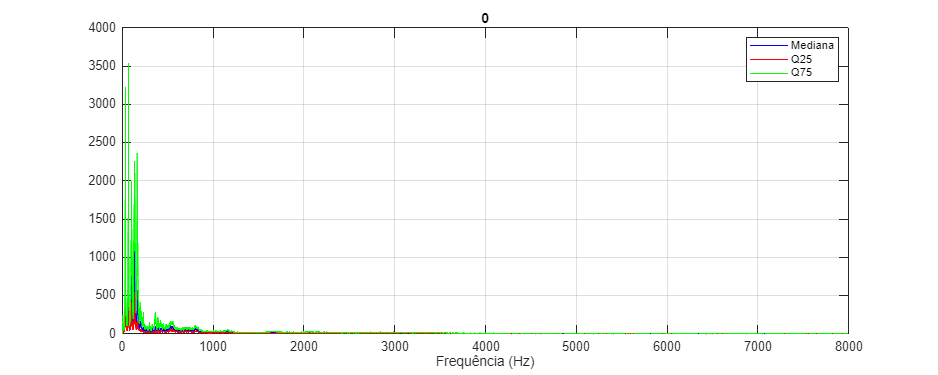

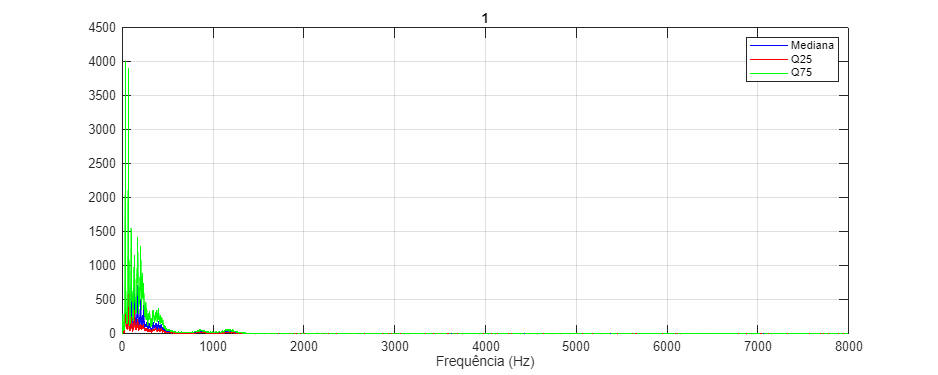

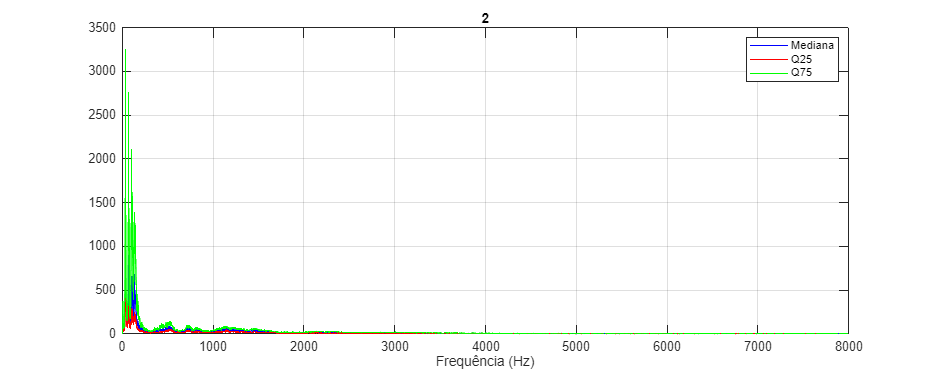

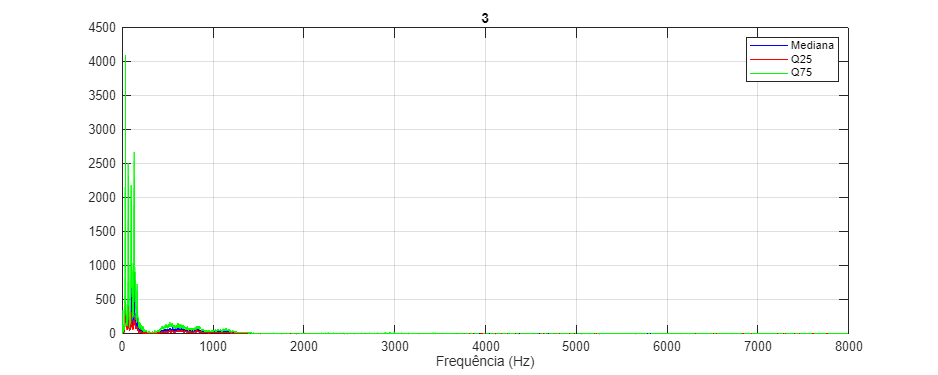

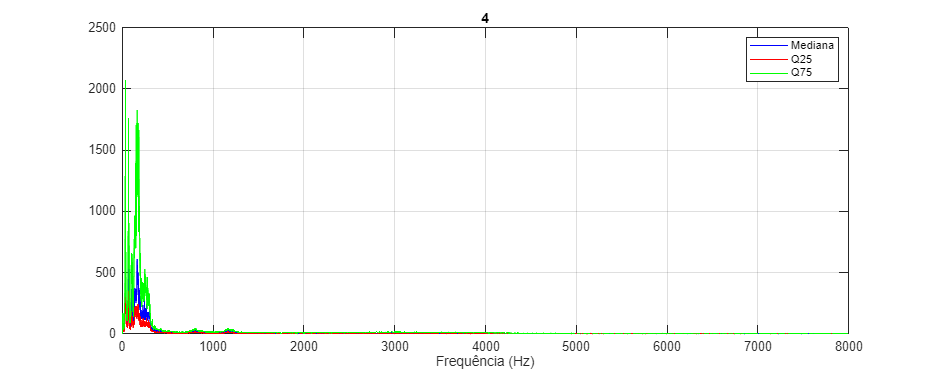

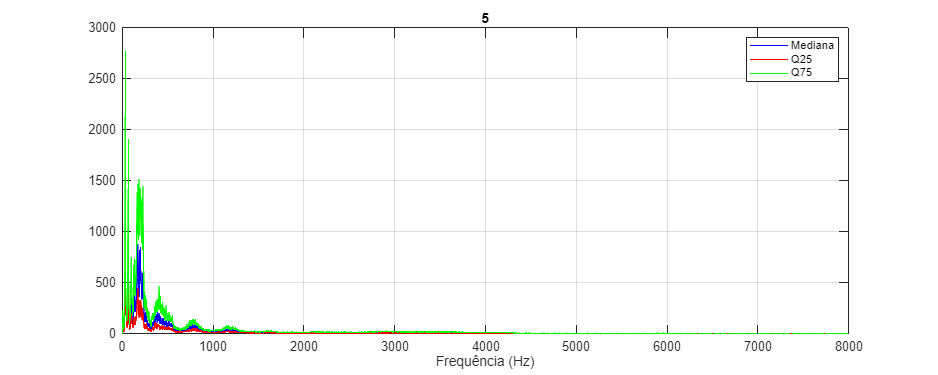

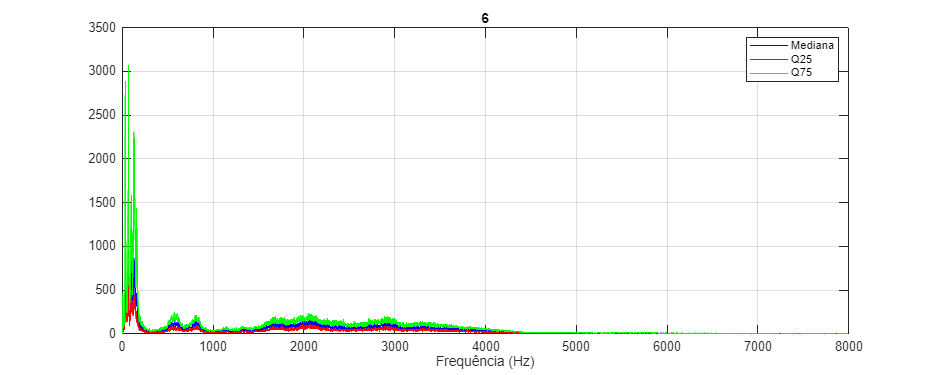

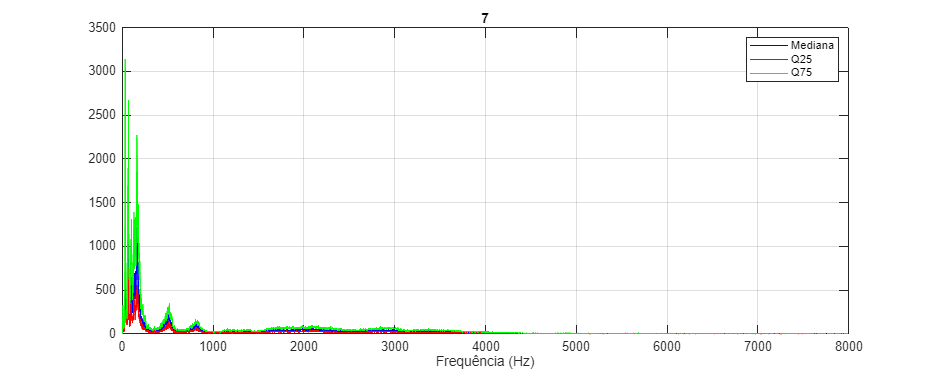


for digito = 0:9
    indices = find([dados.digito] == digito);
    espectro = [];
    
    for i = indices
        sinal = dados(i).coeficientesFourier; 
        N = length(sinal);
        
        % Normalizar o espectro pelo número de amostras
        
        amplitudeFrequencias = abs(sinal);
        
        % Selecionar somente as frequências positivas:

        amplitudeFrequencias = amplitudeFrequencias(1:N/2);

        dados(i).('amplitudeFrequescias') = amplitudeFrequencias;

        espectro = [espectro; amplitudeFrequencias(:)'];
    end
    
    % Cálculo da mediana, Q25 e Q75 para cada frequência:
    mediana = median(espectro, 1);
    q1 = quantile(espectro, 0.25, 1);
    q3 = quantile(espectro, 0.75, 1);
    
    % Vetor de frequências para o eixo x:
    numFrequencias = size(espectro,2);
    vetorFrequencias = linspace(0, 8000, numFrequencias);
    
    % Plot do espectro para o dígito atual:
    figure('Position', [100, 100, 1000, 400]);
    plot(vetorFrequencias, mediana, 'b'); hold on;
    plot(vetorFrequencias, q1, 'r');
    plot(vetorFrequencias, q3, 'g');
    title(num2str(digito));
    xlabel('Frequência (Hz)');
    legend('Mediana', 'Q25', 'Q75');
    grid on;
end

13. Identifique e implemente o cálculo de possíveis características espectrais que permitam a diferenciação entre dígitos como: máximos espectrais (posição e amplitude), médias espectrais,

spectral edge frequency, etc. Deverá efetuar o cálculo para cada áudio de pelo menos 5 características espectrais e atualizar a sua estrutura de dados.

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    amplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    amplitudeFrequescias
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    _______________    ______________    ____________    ___________________    ____________________


for digito = 0:9
    indices = find([dados.digito] == digito);
    espectro = [];
    
    for i = indices
        amplitudeFrequencias = dados(i).amplitudeFrequescias; 
        espectro = [espectro; amplitudeFrequencias(:)'];
    end

    mediana = median(espectro, 1);
    
    % Cálculo do máximo espectral (posição e amplitude)
    [maxAmp, idxMax] = max(mediana);
    maxFreq = vetorFrequencias(idxMax);

    % Cálculo da média espectral
    meanFreq = sum(vetorFrequencias .* mediana) / sum(mediana);
    
    % Cálculo da Spectral Edge Frequency (SEF 95%)
    cumulativePower = cumsum(mediana); % Soma cumulativa da potência
    totalPower = cumulativePower(end); % Potência total
    idxSEF = find(cumulativePower >= 0.95 * totalPower, 1);
    SEF = vetorFrequencias(idxSEF);
    
end

% Inicializar as caracteristicas a cruzar...
valores1 = SEF;
valores2 = meanFreq;
valores3 = idxMax;
digitos = [dados.digito];

figure;
scatter3(valores1, valores2, valores3, 20, digitos, 'filled');  
xlabel('RSEF');
ylabel('meanFreq');
zlabel('idxMax');
grid on;
title('Distribuição das Características do Áudio');

colormap(jet(10));  
caxis([0 9]); 
cor = colorbar;
cor.Ticks = 0:9;  
cor.TickLabels = {'0','1','2','3','4','5','6','7','8','9'};